global L theta d n
n = 6;
m = 8;
d = 3;
size = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
v=eig(L);
lambda_min = min(v(v>0.0001))

lambda_min = 0.2450

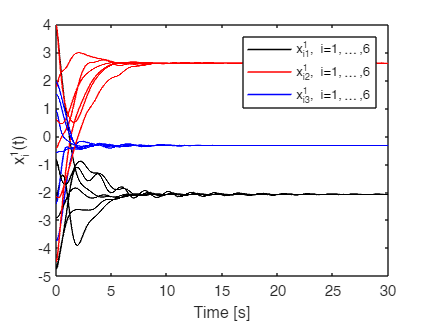

theta4 = 3; theta5 = 0.5; theta6 = [2; 1];
theta = [theta4; theta5; theta6];
theta0 = 3*rand(4,1);
x0 = 10*(rand(d*n,1)-0.5);
r0 = [x0;zeros(d*n,1);theta0];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Consensus
[t,r] = ode45(@adap_consensus,[0:0.01:30],r0,options);
r = r';
x1 = r(1:d*n,:);
x2 = r(d*n+1:2*d*n,:);
theta_hat = r(2*d*n+1:end,:);

e1 = zeros(length(t),1);
for i=1:length(t)
    e1(i,1) = norm(L*x1(:,i));
end

figure
hold on;
for i=1:n
   plot(t,x1(3*i-2,:),'-k','LineWidth',1);
   plot(t,x1(3*i-1,:),'-r','LineWidth',1);
   plot(t,x1(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^1(t)';
box on;
legend({'x_{i1}^1, i=1,\ldots,6','x_{i2}^1, i=1,\ldots,6','x_{i3}^1, i=1,\ldots,6'},"NumColumns",1)

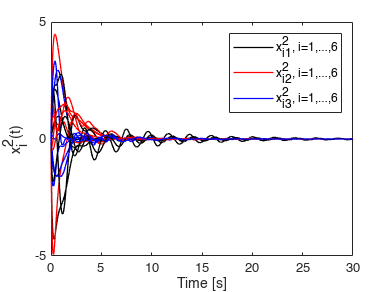


figure
hold on;
for i=1:n
   plot(t,x2(3*i-2,:),'-k','LineWidth',1);
   plot(t,x2(3*i-1,:),'-r','LineWidth',1);
   plot(t,x2(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel 'x_i^2(t)';
box on;
legend({'x_{i1}^2, i=1,\ldots,6','x_{i2}^2, i=1,\ldots,6','x_{i3}^2, i=1,\ldots,6'},"NumColumns",1)

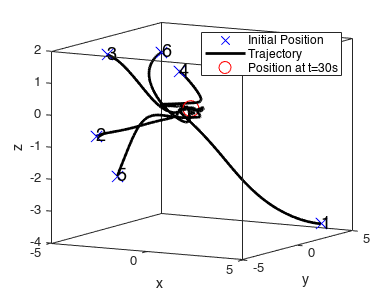



figure
hold on;
for i=1:n
   plot3(x1(3*i-2,1),x1(3*i-1,1),x1(3*i,1),'xb','MarkerSize',12);
   plot3(x1(3*i-2,:),x1(3*i-1,:),x1(3*i,:),'-k','LineWidth',2);
   plot3(x1(3*i-2,end),x1(3*i-1,end),x1(3*i,end),'or','MarkerSize',12);
   text(x1(3*i-2,1),x1(3*i-1,1),x1(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t=30s'}, "NumColumns", 1)
view(30,10)

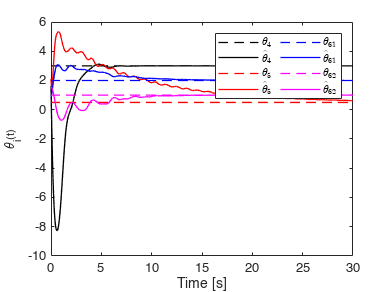


figure
hold on;
plot(t,theta(1,1)*ones(length(t),1),'--k','LineWidth',1);
plot(t,theta_hat(1,:),'-k','LineWidth',1);
plot(t,theta(2,1)*ones(length(t),1),'--r','LineWidth',1);
plot(t,theta_hat(2,:),'-r','LineWidth',1);
plot(t,theta(3,1)*ones(length(t),1),'--b','LineWidth',1);
plot(t,theta_hat(3,:),'-b','LineWidth',1);
plot(t,theta(4,1)*ones(length(t),1),'--m','LineWidth',1);
plot(t,theta_hat(4,:),'-m','LineWidth',1);
xlabel 'Time [s]'; ylabel '\theta_i(t)';
box on;
legend({'$\theta_4$','$\hat{\theta}_4$','$\theta_5$','$\hat{\theta}_5$',...
    '$\theta_{61}$','$\hat{\theta}_{61}$','$\theta_{62}$','$\hat{\theta}_{62}$'},...
    "NumColumns",2,'interpreter', 'latex');

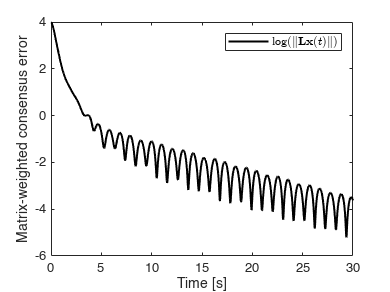


figure
plot(t,log(e1)','-k','LineWidth',1.5)
xlabel 'Time [s]'; ylabel 'Matrix-weighted consensus error';
box on; 
legend({'$\log(\|\mathbf{L}\mathbf{x}(t)\|)$'},"Interpreter",'latex',"NumColumns",1)

function dx = adap_consensus(t,r)
    global L theta d n
    gamma = 1.5; k = 1;
    x1 = r(1:d*n,1);
    x2 = r(d*n+1:2*d*n,1);
    theta_hat = r(2*d*n+1:end,1);
    s = x2 + L*x1;
    uc = -k*s-L*x1-L*x2;
    phi4 = [cos(3*t); 1; 0];
    x51 = x1(13,1); x52 = x1(14,1); x61 = x1(16,1);
    phi5 = [cos(3*t)+0.1*sin(5*t); 0; 0.5*(x51+x52)*sin(5*t)];
    phi6 = [0.15*sin(5*t+1) 0; 0.5*sin(5*t) x61*sin(3*t); sin(2*t) 0];
    u_adapt = [zeros(9,1); phi4*(theta(1)-theta_hat(1)); phi5*(theta(2,1)-theta_hat(2,1)); phi6*(theta(3:4,1)-theta_hat(3:4,1))];
    dtheta4 = gamma*phi4'*s(10:12,1);
    dtheta5 = gamma*phi5'*s(13:15,1);
    dtheta6 = gamma*phi6'*s(16:18,1);
    dtheta = [dtheta4;dtheta5;dtheta6];
    dx = [x2; uc + u_adapt; dtheta];
end
